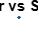

% Digital PAM simulation with probability of error analysis

clear all;
close all;

% Parameters
N = 10000;      % Data sequence length
M = 4;          % Modulation order (number of levels)
SNR_dB = -10:2:20; % Signal-to-Noise Ratio in dB

% Data generation
data = randi([0 M-1], 1, N);

% PAM modulation
pam = (2*data-M+1);

% Loop over SNR values
for i = 1:length(SNR_dB)
    % Channel noise
    SNR = 10^(SNR_dB(i)/10);
    sigma = sqrt(1/SNR);
    noise = sigma*randn(1, N);

    % Transmission over channel
    received = pam + noise;

    % PAM demodulation
    data_hat = (received > 0).*floor((received+1)/2);

    % Probability of error calculation
    P_e(i) = sum(data~=data_hat)/N;
end

% Plot probability of error vs SNR
figure;
semilogy(SNR_dB, P_e);
grid on;
xlabel('SNR (dB)');
ylabel('Probability of Error');
title(['Probability of Error vs SNR for ' num2str(M) '-level PAM']);